clear
load ../input/PBP2_msa_889.mat
msa = msa_w_dist.msaResult;
gapCols = msa(end, :) == '-';
msa(:, gapCols) = [];

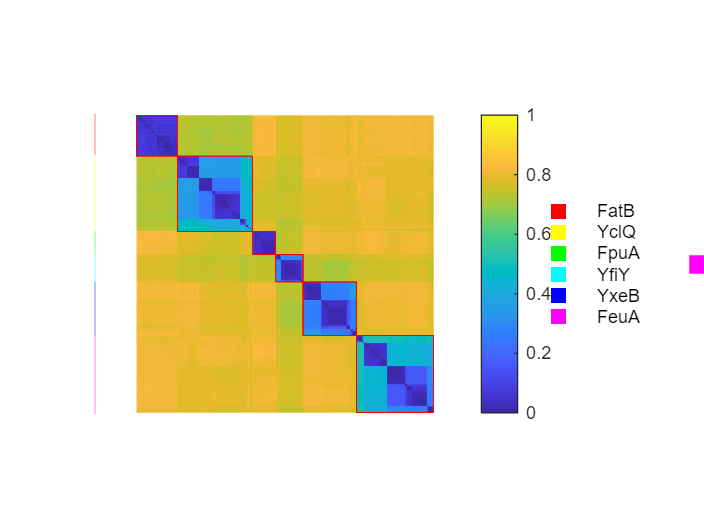

distm =squareform(seqpdist(msa, 'Method', 'p-distance','PairwiseAlignment', false));
tree = linkage(distm,'average');
leafOrder = optimalleaforder(tree,distm);
dist_thresh = 0.5;
[metallore_groupid,metallore_groupnum,changedleaforder_bygroups] = Cluster_byconnection(distm,dist_thresh,leafOrder);
distm_reorder = distm(changedleaforder_bygroups,changedleaforder_bygroups);
group_info = msa_w_dist.rec_name(changedleaforder_bygroups);
group_number = msa_w_dist.rec_group(changedleaforder_bygroups);
syn_group_number = msa_w_dist.syn_group(changedleaforder_bygroups);
metallore_groupid = metallore_groupid(changedleaforder_bygroups);
plot_cluster_colorbar(distm_reorder,metallore_groupid,group_info,'../Figure/6_receptors_cluster.pdf')

dist_vec = squareform(distm_reorder);  
if isrow(group_number)
    group_number_col = group_number';
end
s = silhouette([], group_number_col, dist_vec);
avg_silhouette = mean(s)

avg_silhouette = 0.7206

%%%compute Mutuall information
gapthresh = 1; 
msa_reoreder = msa(changedleaforder_bygroups,:);
groups = group_number';
gapfreq = sum(msa_reoreder == '-', 1) / size(msa_reoreder, 1); 
goodlist = find(gapfreq < gapthresh); 

mi_values = zeros(1, size(msa_reoreder,2)); 

for i = 1:length(goodlist)
    pos = goodlist(i);
    col_data = msa_reoreder(:, pos); 
    unique_symbols = unique(col_data); 
    unique_groups = unique(groups); 

    joint_counts = zeros(length(unique_symbols), length(unique_groups));
    for j = 1:length(unique_symbols)
        for k = 1:length(unique_groups)
            joint_counts(j, k) = sum(col_data == unique_symbols(j) & groups == unique_groups(k));
        end
    end
    joint_probs = joint_counts / sum(joint_counts(:)); 

    symbol_probs = sum(joint_probs, 2);
    group_probs = sum(joint_probs, 1);

    mi = 0;
    for j = 1:length(unique_symbols)
        for k = 1:length(unique_groups)
            if joint_probs(j, k) > 0
                mi = mi + joint_probs(j, k) * log2(joint_probs(j, k) / (symbol_probs(j) * group_probs(k)));
            end
        end
    end
    mi_values(goodlist(i)) = mi; 
    mi_values_goodlist(i) = mi;
end 

%compute theoretical maximum
st_groups = tabulate(groups);
[~, gi] = sort(st_groups(:, 2), 'descend');
st_groups = st_groups(gi, :)

st_groups =     6.0000  230.0000   25.8718
    3.0000  225.0000   25.3093
    2.0000  161.0000   18.1102
    4.0000  122.0000   13.7233
    1.0000   82.0000    9.2238
    5.0000   69.0000    7.7615


group_counts = st_groups(1:6,2);
total_samples = sum(group_counts);
group_probs = group_counts / total_samples;
H_Y = -sum(group_probs .* log2(group_probs))

H_Y = 2.4494

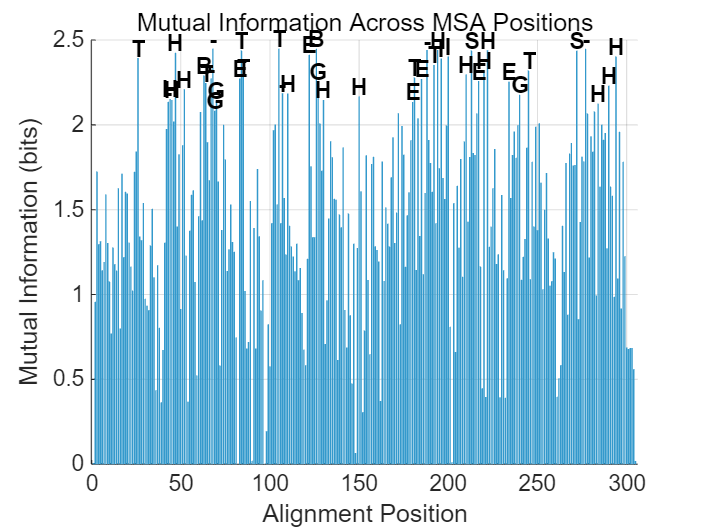


load ../input/full_sec_struct.mat
aligned_sec_struct = full_sec_struct;
threshold = 0.85*(H_Y);
top_15_percent_indices = find(mi_values >= threshold);


default_color = [0.2, 0.6, 0.8]; 
gap_color = [1, 0, 0]; 

bar_colors = repmat(default_color, size(msa_reoreder, 2), 1); % 默认颜色矩阵


figure;
hold on;
for i = 1:size(msa_reoreder, 2)
    bar(i, mi_values(i), 'FaceColor', bar_colors(i, :), 'EdgeColor', 'none');
end

for i = 1:length(top_15_percent_indices)
    idx = top_15_percent_indices(i);
    text(idx, mi_values(idx) + 0.05, aligned_sec_struct(idx), ...
        'FontSize', 10, 'FontWeight', 'bold', 'HorizontalAlignment', 'center');
end

h1 = bar(NaN, NaN, 'FaceColor', default_color, 'EdgeColor', 'none');

lgd.Box = 'off';

title('Mutual Information Across MSA Positions');
xlabel('Alignment Position');
ylabel('Mutual Information (bits)');
grid on;
hold off;

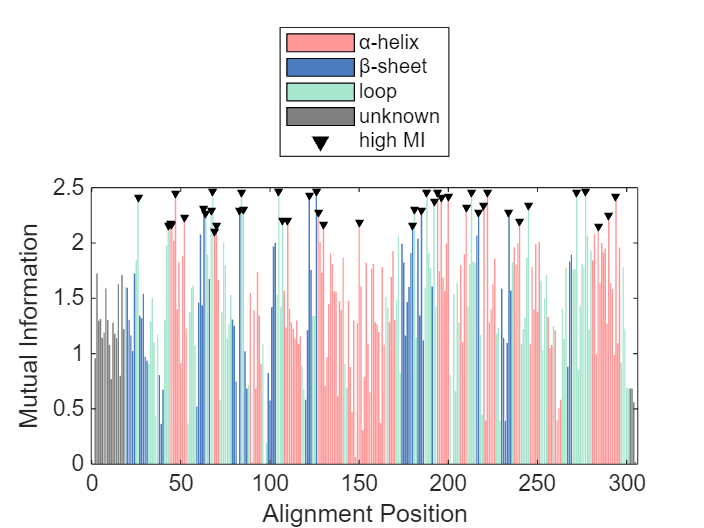

helix_color = [1.00, 0.60, 0.60];       

loop_color = [0.66, 0.90, 0.81];        
undefined_color = [0.5, 0.5, 0.5];      

sheet_color = sscanf('#4B7CBE', '#%2x%2x%2x', [1 3]) / 255;

bar_colors = zeros(size(msa, 2), 3);
for i = 1:size(msa, 2)
    sec = aligned_sec_struct(i);
    if ismember(sec, ['H', 'G', 'I'])
        bar_colors(i, :) = helix_color;
    elseif ismember(sec, ['E', 'B'])
        bar_colors(i, :) = sheet_color;
    elseif ismember(sec, ['C', 'S', 'T','-'])
        bar_colors(i, :) = loop_color;
    else
        bar_colors(i, :) = undefined_color;
    end
end

figure;
ax1 = axes;
bar(ax1, 1:size(msa,2), mi_values, 'FaceColor', 'flat', ...
    'CData', bar_colors, 'EdgeColor', 'none');
hold on;

scatter(ax1, top_15_percent_indices, mi_values(top_15_percent_indices) + 0.02, ...
    8, 'v', 'filled', 'MarkerFaceColor', 'k', 'MarkerEdgeColor', 'k');

h1 = bar(nan, nan, 'FaceColor', helix_color);
h2 = bar(nan, nan, 'FaceColor', sheet_color);
h3 = bar(nan, nan, 'FaceColor', loop_color);
h4 = bar(nan, nan, 'FaceColor', undefined_color);
h5 = scatter(nan, nan, 30, 'v', 'filled', 'MarkerFaceColor', 'k', 'MarkerEdgeColor', 'k');
legend([h1, h2, h3, h4, h5], ...
    {'α-helix', 'β-sheet', 'loop', 'unknown', 'high MI'}, 'Location', 'northoutside');

xlabel('Alignment Position');
ylabel('Mutual Information');

%cluster rec by Feature sites
index1 = find(mi_values > 0.85*(H_Y))

index1 =     26    43    44    45    47    52    63    64    67    68    69    70    83    84    85   105   107   110   122   126   127   130   150   180   181   185   188   192   194   196   200   210   213   217   220   222   234   240   245   272   277   284   290   294


msa_test=msa_reoreder(:,index1);
distm_test = squareform(seqpdist(msa_test,'PairwiseAlignment',false,'Method','p-dist'));


dist_vec2 = squareform(distm_test);  
if isrow(group_number)
    group_number_col = group_number';
end
s = silhouette([], group_number_col, dist_vec2);
avg_silhouette = mean(s)

avg_silhouette = 0.8462

loc = find(strcmp(msa_w_dist.filename(changedleaforder_bygroups),'Bacillus subtilis'))

loc = 868

FeuA_sequences = msa_reoreder(loc,:);
mapping = zeros(1, length(FeuA_sequences));
original_pos = 0;

for i = 1:length(FeuA_sequences)
    if FeuA_sequences(i) ~= '-'
        original_pos = original_pos + 1;
        mapping(i) = original_pos;
    else
        mapping(i) = 0;
    end
end

high_MI_residues = mapping(index1);
high_MI_residues = high_MI_residues(high_MI_residues ~= 0);
if isempty(high_MI_residues)
    error('No valid residues to select.');
else
    
   residues_str = strjoin(cellstr(num2str(high_MI_residues')), '+'); % 用 + 连接，无空格
   cmd = ['select hotspots, resi ' residues_str];
   disp(cmd);
end

select hotspots, resi  26+ 43+ 44+ 45+ 47+ 52+ 63+ 64+ 67+ 68+ 69+ 70+ 83+ 84+ 85+105+107+110+122+126+127+130+150+180+181+185+188+192+194+196+200+210+213+217+220+222+234+240+245+272+277+284+290+294
